# Hadamard Single-pixel Imaging

This example demonstrates how `otslm.simple.hadamard` can be used to generate patters for display on a digital micro-mirror device (DMD) for single-pixel imaging (SPI).

SPI involves using a single-pixel detector, such as a photo-diode, to generate an image of a light source or object by sampling light from different regions and computationally forming an image.  Devices including DMDs can be used to apply masks to the light before the light is focussed onto the detector.

Instead of scanning through each pixel on the DMD to directly build up an image, it is possible to use a set of basis functions to build up an image with far-fewer samples by first sampling lower frequency components and then sampling higher frequency components (sharp lines/edges).  This method may be less sensitive to noise and can produces decent looking images in far-fewer samples.  There are many different patterns which could be displayed on the device, one such pattern is based on the Hadamard matrix.  This example shows how these patterns can be generated and used for SPI.

## Generate the target image

The following code generates the target that we want to form an image of.  For this example we generate a pattern that is a mixture of two other `otslm.simple` functions

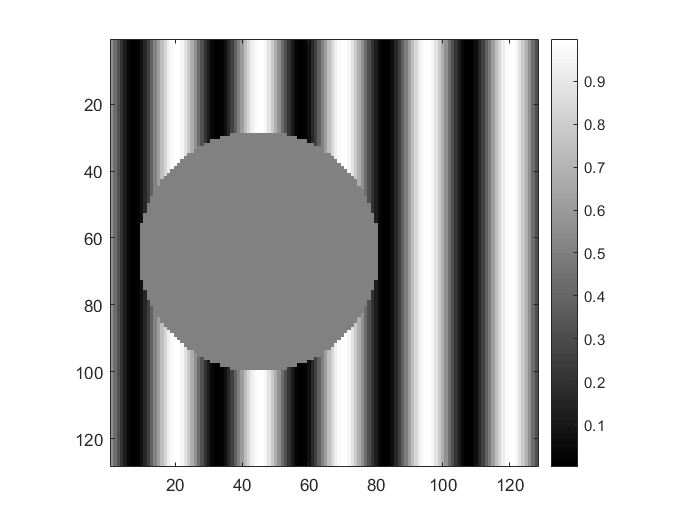

addpath('../../');   % Add OTSLM to the path (if not already done)

sz = [1, 1]*128;
target = otslm.simple.sinusoid(sz, 25);
target(otslm.simple.aperture(sz, 36, 'shape', 'circle', 'centre', [45, 64])) = 0.5;
figure(), imagesc(target), axis image, colormap gray, colorbar

## Setup DMD for SPI

We use `otslm.utils.TestDmd` and a `otslm.utils.TestFarField` devices for simulating the DMD and simulating the lense used to capture light from the object and project it onto our detector.

The target can either be placed as a mask after the DMD or as an obstruction to the incident illumination before the DMD, in this case we choose to apply the mask to the incident illumination.

The single-pixel detection scheme only has a single-pixel, in this case we sum all the output from the view method.

dmd = otslm.utils.TestDmd('size', sz, 'use_rpack', false, ...
    'incident', target);
farfield = otslm.utils.TestFarfield(dmd);
view = @() sum(sum(farfield.view()));

## Collect SPI measurements to generate an image

To construct an image with the Hadamard basis images, we need to calculate


$$P=\sum_{u,v} w_{u,v} \;H\left(u,v\right)\;$$


where $H(u, v)$are the Hadamard basis images and $w_{u, v}$ can be calculated from two SPI measurements: the first measurement with the basis image $H$, and the second with the inverted image $1-H$.

When we generate the Hadamard basis patterns with the `'largetosmall' `ordering option, the patterns with the largest solid regions will have lower $u,v$ indexes and patterns describing higer frequency features will have higher indices.

For this example, we build up the image starting with the (1, 1) coordinates and moving diagonally across the image.  The `numdiag` slider bellow controls how many diagonal rows are included before stopping.  

numdiag = 34;

% To start to see some resemblance, we need about a 5% sampling ratio

disp(['Num-measurements (approx): ' num2str(numdiag.^2/2)]);

Num-measurements (approx): 578


disp(['Sampling ratio (approx): ' num2str(numdiag.^2/2 ./ prod(sz))]);

Sampling ratio (approx): 0.035278


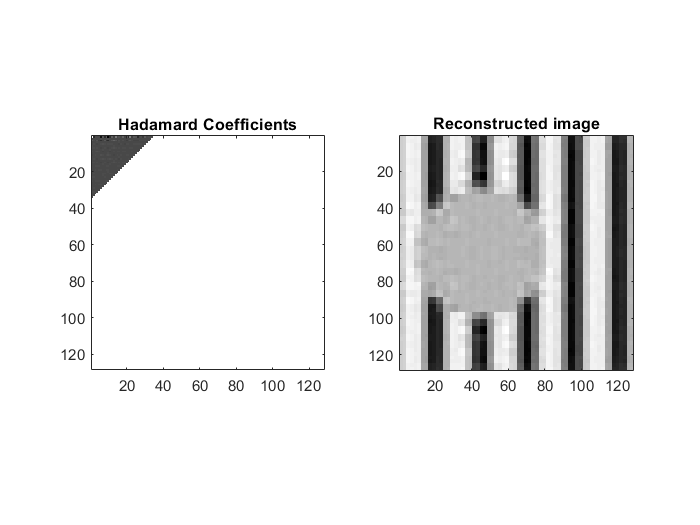


% Allocate/clear arrays for output
weights = nan(sz);
Pimage = zeros(sz);


for ii = 1:numdiag
    
    % Uncomment to show progress
%     disp(['Calculating row: ' num2str(ii)]);
    
    for jj = 1:ii
        
        u = ii - jj + 1;
        v = jj;
        
        if u > sz(1) || v > sz(1)
            continue;
        end
        
        H = otslm.simple.hadamard(sz, u, v, 'order', 'largetosmall');
        
        % Apply the pattern and view the result
        dmd.show(H);
        w1 = view();
        
        dmd.show(1.0 - H);
        w2 = view();
        
        weights(u, v) = w2 - w1;
        
        % Update our best guess at the image
        Pimage = Pimage + weights(u, v) .* H;
    end
end
    
figure();
subplot(1, 2, 1);
imagesc(weights, 'AlphaData', ~isnan(weights)), axis image, colormap parula
title('Hadamard Coefficients')
subplot(1, 2, 2);
imagesc(Pimage), axis image, colormap gray
title('Reconstructed image')

## Random sample SPI

Instead of using structured sampling, we could also use random sampling.  The bellow example shows the reconstructed image after `numsamples` samples.

numsamples = 1301

numsamples = 1301


disp(['Sampling ratio (approx): ' num2str(numsamples ./ prod(sz))]);

Sampling ratio (approx): 0.079407


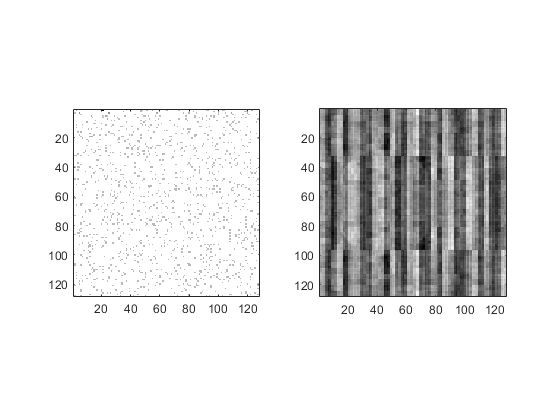


% Allocate/clear arrays for output
weights = nan(sz);
Pimage = zeros(sz);

for ii = 1:numsamples
    
    u = randi(sz(1));
    v = randi(sz(1));
    
    H = otslm.simple.hadamard(sz, u, v, 'order', 'largetosmall');
    
    % We should realy check that this sample hasn't already been read!
        
    % Apply the pattern and view the result
    dmd.show(H);
    w1 = view();
    
    dmd.show(1.0 - H);
    w2 = view();
    
    weights(u, v) = w2 - w1;
    
    % Update our best guess at the image
    Pimage = Pimage + weights(u, v) .* H;
    
end
    
figure();
subplot(1, 2, 1);
imagesc(weights, 'AlphaData', ~isnan(weights)), axis image, colormap parula
title('Hadamard Coefficients')
subplot(1, 2, 2);
imagesc(Pimage), axis image, colormap gray

title('Reconstructed image')


## About

This example live script is part of OTSLM.  Written by Isaac Lenton.  For further details see [https://github.com/ilent2/otslm](https://github.com/ilent2/otslm)